# Meet the EMG data

In exampleEMGdata30trials.mat, you have been given some EMG data. We'll call the measurement "adjusted voltage".

These data have been "preprocessed" for you. The data started as a long stream of 4 channels (electrodes) of data. They were high pass filtered above 5 Hz and then chopped up into 30 separate Trials.

Fs is the sampling frequency (how many times per second a datapoint is recorded). actualFs is 1 / (the average of the time between each sample from the data).  It's okay for us to just assume that the standard sampling frequency is correct enough if these are close, but the value is here to show us that sampling rate is not perfect.

The labels are 1 (rock), 2 (paper), 3 (scissors). The size of the labels vector should match the number of trials. We can make a string array to store these labels. 

label_rps = string(["rock","paper","scissors"])

label_rps = 1×3 string array
    "rock"    "paper"    "scissors"


The following set of questions and exercises are intended to walk you through making sense of the data. 

Using the size function, you can see that the data has 3 dimensions (channels x timepoints x trials). 

#### Exercise: Make a time vector time_ms that starts at zero and shows the time of each trial in milliseconds. 

You can use Fs or actualFs, whichever you prefer.

Hints: 

The number of timepoints should match the number of values in your time_ms vector. 

The sampling rate will help you determine the number of ms between each timepoint. Remember that sampling rate is samples per second, but we want milliseconds.

timestep = (1/actualFs)*1000; %in ms
time_ms = 0:timestep:timestep*1399;

time_ms =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


#### Exercise: Make a plot of the data for any single channel (ch) and any single trial (tr) versus time_ms. Include axis labels and a title that indicates (with a word) which condition this is from (rock, paper, or scissors). 

Check for multiple channels and trials by changing the values of ch and tr. 

Hints:

Use the variables ch and tr to find the right parts of dataChTimeTr. If it's helpful to pick real numbers to start, you can use channel 1 and trial 2. 

To get the proper title, you'll need label_rps, labels, and the variable that indicates which trial.

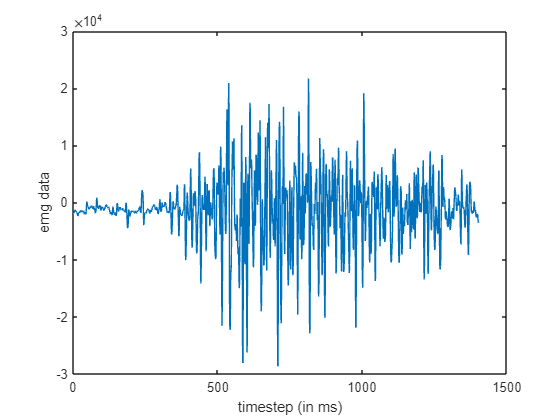

ch = 3;
tr = 1;
clf; 
figure; 
plot(time_ms, dataChTimeTr(ch, :, tr))
xlabel("timestep (in ms)"); 
ylabel("emg data"); 

You should see a squiggly line. 

#### Exercise: Make plot that shows all of the "rock" trials for some channel (ch).

Each trial should be a line on the same graph. Be sure to label. It may be useful later to create a varible called cond, which indicates which condition (e.g., 1 for rock). 

You will need to use the squeeze() function to make the dimensions the proper size for plotting so you can tell Matlab to ignore the extra dimensions. I suggest that you store the data you are about to plot in a variable called cond_signals  (for condition signals).

Hint:

cond_signals should be a 1400 x 10 matrix.

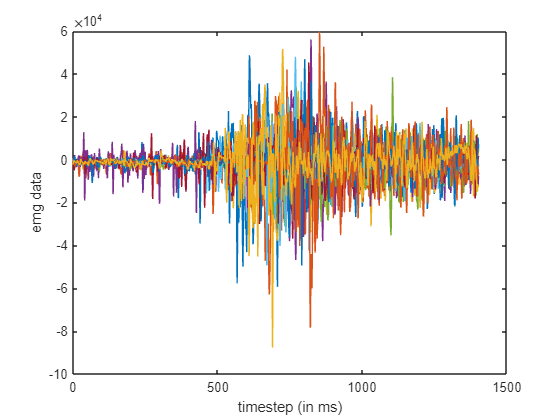


ch =1; %channel
cond = 1; % condition

cond_signals = dataChTimeTr(ch, :, find(labels==cond)); 

clf; 
figure; 
plot(time_ms, squeeze(cond_signals))
xlabel('timestep (in ms)')
ylabel('emg data')

#### Exercise: Make a grid of plots with a row for each condition (e.g. rock) and a column for each channel (1-4).  Each plot should contain all the trials for that condition as an image. 

The x-axis should be the timepoints and the y-axis should be trial number. The colors should represent the adjusted voltage. The title should indicate the channel number and condition.

The shell code below is intended to save you some time.

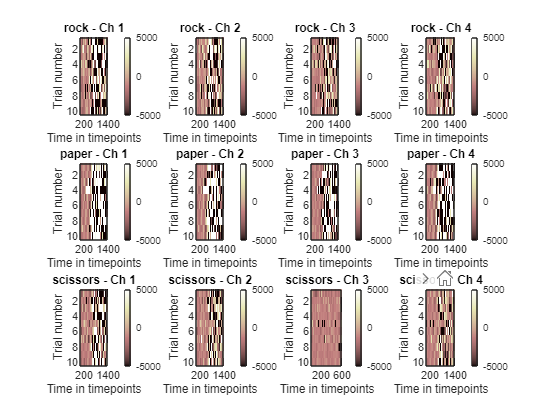

numCond = length(label_names);
figure;
p = 1; %index which subplot

for cond = 1:numCond % condition 
    for ch = 1:numCh
        subplot(numCond,numCh, p);
        
        data = squeeze(dataChTimeTr(ch, :, find(labels==cond)));
        imagesc(data');


        xlabel("Time in timepoints"); ylabel("Trial number");
        title(strcat(label_rps(cond)," - Ch ", num2str(ch)));
        colorbar; clim([-5000 5000]); colormap('pink')
        p = p+1; %Increment to next plot.
    end
end

Pop the figure out of the Matlab notebook window and make it full screen so you can make better observations.

#### Exercise: Write at least 3 observations about these plots. What do you generally observe about the change in signal (color) over time?  Do all trials look the same? Can you observe any differences between the conditions in a channel?

Over time, the rock signals fade into darker+more sparse spots of brown and white while the paper signals stay more saturated and have a clearer cutoff, and the scissors also are more saturated but for longer than paper. The trials aren't very consistent within each channel but the trials across the four channels are consistent with each other. For example, trial 6 for scissors is consistent across each channel and so on. 

## Feature extraction

In Part 1 of this course, we started to learn about feature extraction. With the fMRI data, we extracted an average value of different brain regions (r1, r2) and used those mean as our features. 

With EMG data, we have lots of options for interesting features to use. For now, we will just meet one: variance.

You may have observed that the signals above were squiggly lines, but perhaps some made bigger squiggles than others. 

Let's look at the very first plot we made, but instead of a line, we'll mark each data point as a dot.

We'll also add a red line that is the mean value. 

ch = 3;
tr = 1;
one_signal = dataChTimeTr(ch,:,tr);
mean_value = mean(one_signal)

mean_value = -1.2879e+03

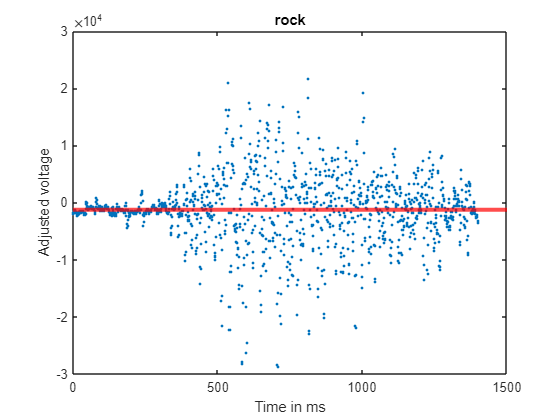

figure
plot(time_ms, one_signal,'.'); hold on;
yline(mean_value,'r','LineWidth',3);
xlabel("Time in ms"); ylabel("Adjusted voltage"); title(label_rps(labels(tr)));

The variance is the average squared distance between each blue dot and the red line. The square root of the variance is the standard deviation. We can use the variance a measure of how much variability there is in our data (how far away the datapoints tend to be from the mean)^2.

#### Exercise: Calculate the variance among the timepoints for each trial and channel.

Hint: 

You can do this in one line of code. You probably need to read the documentation for var(). 

You can use squeeze() if you have a pesky middle dimension of size==1 and you want to get rid of it (it's okay to leave it).

variance = var(one_signal)

variance = 3.4204e+07

#### Exercise: Make 3 histograms of the variance on the same figure, one for each condition. Set channel to a variable you can change, but you only need to show one channel at a time.

I suggest you use:

histogram(mydata, 'BinEdges', bins_for_hist)

in order to get bins that are the same size across your conditions.

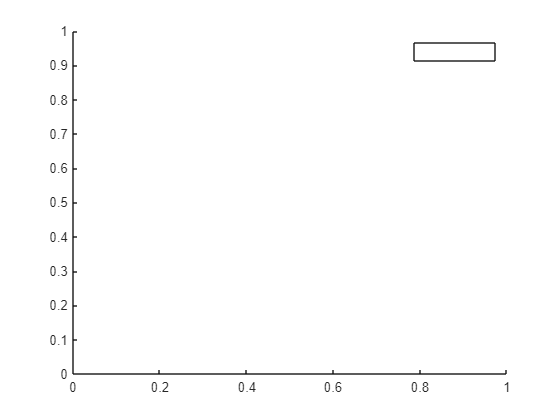

ch =1;
bins_for_hist = 0:10^7:10^9;
figure;


legend(label_rps)

#### Exercise: What do you observe about the variance histogram? What does this tell you about how easy or difficult it might be to build a rock, paper, scissors classifier using only this feature?